% Punkt 1
clear all;
K0 = 6.4;
T0 = 5.0;
T1 = 2.07;
T2 = 4.6;
Tp = 0.5;

s = tf('s');
G_s = (K0 * exp(-T0 * s)) / ((T1 * s + 1) * (T2 * s + 1));
disp('Transmitancja ciągła G(s):');

Transmitancja ciągła G(s):


disp(G_s);

  tf with properties:

       Numerator: {[0 0 6.4000]}
     Denominator: {[9.5220 6.6700 1]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 5
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]




G_z = c2d(G_s, Tp, 'zoh');
disp('Transmitancja dyskretna G(z):');

Transmitancja dyskretna G(z):


disp(G_z);

  tf with properties:

       Numerator: {[0 0.0748 0.0666]}
     Denominator: {[1 -1.6824 0.7045]}
        Variable: 'z'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 10
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0.5000
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



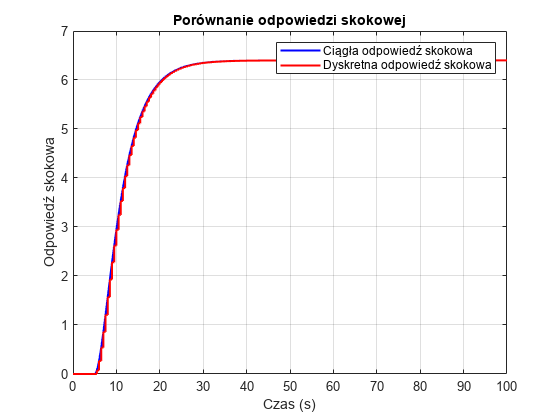


% Porównanie odpowiedzi skokowej transmitancji ciągłej i dyskretnej
t_cont = 0:0.1:100;  % Czas dla odpowiedzi ciągłej
t_disc = 0:Tp:100;   % Czas dla odpowiedzi dyskretnej

% Odpowiedź skokowa dla transmitancji ciągłej
[y_cont, t_cont] = step(G_s, t_cont);

% Odpowiedź skokowa dla transmitancji dyskretnej
[y_disc, t_disc] = step(G_z, t_disc);

% Wykresy odpowiedzi skokowej
figure;
plot(t_cont, y_cont, 'b', 'LineWidth', 1.5); hold on;
stairs(t_disc, y_disc, 'r', 'LineWidth', 1.5);
legend('Ciągła odpowiedź skokowa', 'Dyskretna odpowiedź skokowa');
xlabel('Czas (s)');
ylabel('Odpowiedź skokowa');
title('Porównanie odpowiedzi skokowej');
print ('pics/por_odp_skok.png', '-dpng', '-r400')
grid on;
hold off;


K_static_cont = dcgain(G_s);
disp('Wzmocnienie statyczne transmitancji ciągłej:');

Wzmocnienie statyczne transmitancji ciągłej:


disp(K_static_cont)

    6.4000




K_static_disc = dcgain(G_z);
disp('Wzmocnienie statyczne transmitancji dyskretnej:');

Wzmocnienie statyczne transmitancji dyskretnej:


disp(K_static_disc)

    6.4000




% Punkt 2
% Uzyskanie współczynników transmitancji dyskretnej
[num, den] = tfdata(G_z, 'v');

% Wyświetlenie współczynników licznika i mianownika
disp('Współczynniki licznika:');

Współczynniki licznika:


disp(num);

         0    0.0748    0.0666



disp('Współczynniki mianownika:');

Współczynniki mianownika:


disp(den);

    1.0000   -1.6824    0.7045




% Wyświetlenie równania różnicowego
disp('Równanie różnicowe:');

Równanie różnicowe:


fprintf('y(k) = ');

y(k) = 


% Współczynniki mianownika (a_i) z wyjątkiem pierwszego elementu
for i = 2:length(den)
    if den(i) ~= 0
        fprintf('%+.5f * y(k-%d) ', -den(i), i-1);
    end
end

+1.68242 * y(k-1) -0.70452 * y(k-2) 


% Współczynniki licznika (b_i)
for i = 1:length(num)
    if num(i) ~= 0
        if i == 1
            fprintf('%+.5f * u(k) ', num(i));
        else
            fprintf('%+.5f * u(k-%d) ', num(i), 10+i-1);
        end
    end
end

+0.07485 * u(k-11) +0.06660 * u(k-12) 


fprintf('\n');

% Punkt 3
% Parametry krytyczne
K_k = 0.33136;
T_k = 19.7720;
disp('Parametry krytyczne:');

Parametry krytyczne:


fprintf('K_k = %.4f\n', K_k);

K_k = 0.3314


fprintf('T_k = %.4f\n', T_k);

T_k = 19.7720



% Parametry regulatora PID
K_r = 0.6 * K_k;
T_i = 0.5 * T_k;
K_i = K_r/T_i;
T_d = 0.12 * T_k;
K_d = K_r*T_d;

disp('Parametry regulatora PID:');

Parametry regulatora PID:


fprintf('K_r = %.4f\n', K_r);

K_r = 0.1988


fprintf('T_i = %.4f\n', T_i);

T_i = 9.8860


fprintf('T_d = %.4f\n', T_d);

T_d = 2.3726




% Obliczenie współczynników dyskretnego regulatora PID
r0 = K_r * (1 + Tp / (2 * T_i) + T_d / Tp);
r1 = K_r * (Tp / (2 * T_i) - 2 * T_d / Tp - 1);
r2 = K_r * T_d / Tp;

disp('Współczynniki regulatora dyskretnego PID:');

Współczynniki regulatora dyskretnego PID:


fprintf('r0 = %.4f\n', r0);

r0 = 1.1473


fprintf('r1 = %.4f\n', r1);

r1 = -2.0807


fprintf('r2 = %.4f\n', r2);

r2 = 0.9434


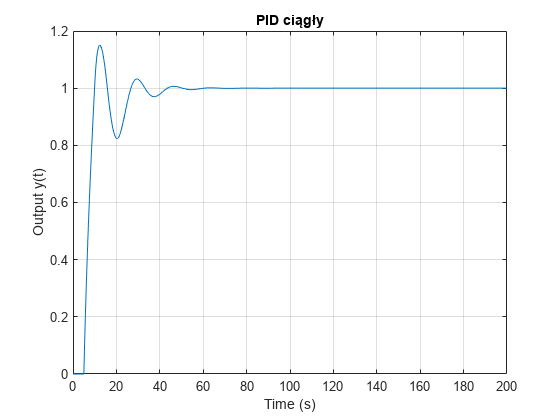


% Punkt 4
% PID ciagly
PID = K_r + K_i/s + K_d*s;

% Closed-loop transfer function
G_cl = feedback(PID * G_s, 1);

% Simulation time
t = 0:0.1:200;

% Step response
[y1, t] = step(G_cl, t);

% Plot the step response
figure;
plot(t, y1);
title('PID ciągły');
xlabel('Time (s)');
ylabel('Output y(t)');
print ('pics/pid_ciag.png', '-dpng', '-r400')
grid on;

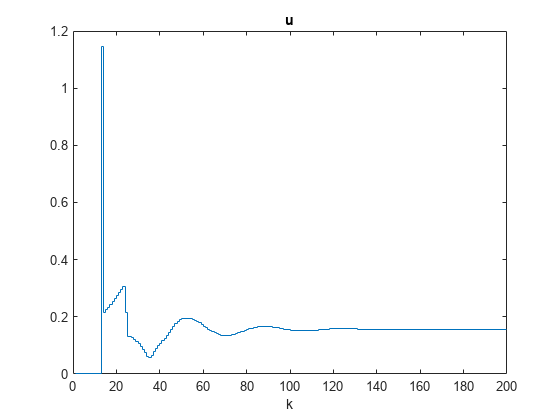


% PID dyskretny

kk = 200; % koniec symulacji
u = zeros(1, kk); % sygnał sterujący
y = zeros(1, kk); % sygnał wyjściowy
yzad = ones(1, kk); % sygnał zadany
e = zeros(1, kk); % uchyb regulacji

% Współczynniki obiektu
c = [num(2), num(3)];
b = [den(1), den(2), den(3)];

for k = 13:kk
    % Symulacja obiektu
    y(k) = c(1)*u(k-11) + c(2)*u(k-12) - b(2)*y(k-1) - b(3)*y(k-2);
    
    % Uchyb regulacji
    e(k) = yzad(k) - y(k);
    
    % Sygnał sterujący regulatora PID
    u(k) = r2 * e(k-2) + r1 * e(k-1) + r0 * e(k) + u(k-1);
end

% Wynik symulacji
figure; stairs(u);
title('u'); xlabel('k');

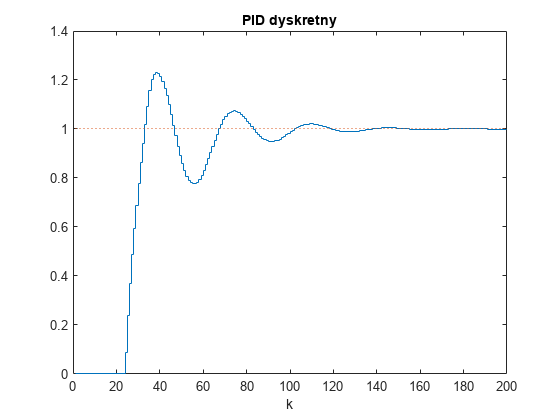

figure; stairs(y); hold on; stairs(yzad, ':');
title('PID dyskretny'); xlabel('k');
print ('pics/pid_dysk.png', '-dpng', '-r400')
hold off;

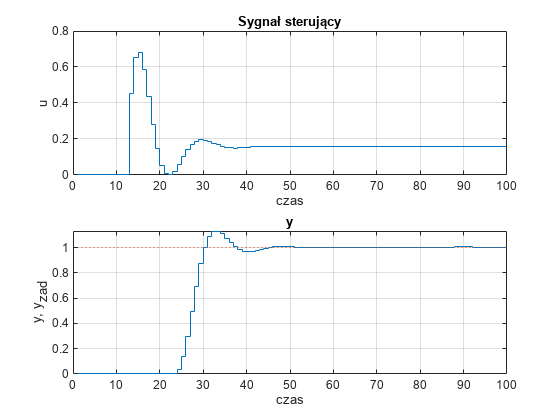


% DMC
kk = 100;
yzad = ones(1, kk);
u = zeros(1, kk);
y = zeros(1, kk);
e = zeros(1, kk);
lambda = 4;
D = 69;
N = 15;
Nu = 1;
s = step(G_z);
s(1) = [];
dup = zeros(1,D-1);

% Macierz M
M = zeros(N, Nu);
for i = 1:N
    for j = 1:Nu
        if (i >= j)
            M(i, j) = s(i-j+1);
        end
    end
end

% Macierz Mp
Mp = zeros(N, D-1);
for i = 1:N
    for j = 1:(D-1)
        if j + i <= D
            Mp(i, j) = s(i+j) - s(j);
        else
            Mp(i, j) = s(D) - s(j);
        end
    end
end

I = eye(Nu);
K = inv((M' * M + lambda * I)) * M';
Ku = K(1,:) * Mp;
Ke = sum(K(1,:));

for k = 13:kk
    % Symulacja obiektu
    y(k) = c(1) * u(k-11) + c(2) * u(k-12) - b(2) * y(k-1) - b(3) * y(k-2);

    % Uchyb regulacji
    e(k) = yzad(k) - y(k);

    % Prawo regulacji
    du = Ke * e(k) - Ku * dup';
    for n = D-1:-1:2
        dup(n) = dup(n-1);
    end

    dup(1) = du;
    u(k) = u(k-1) + dup(1);
end

% Wynik symulacji
figure;
subplot(2, 1, 1);
stairs(u);
hold on; 
grid on;
xlabel('czas'); 
ylabel('u');
title('Sygnał sterujący');

subplot(2, 1, 2);
stairs(y); hold on; stairs(yzad, ':');
hold on; 
grid on;
xlabel('czas'); 
ylabel('y, y_{zad}');
title('y');